# Demonstrates if-blocks.

n1 = input('Enter a number: ');
n2 = input('Enter another number: ');
disp('Test #1')

Test #1


string = 'At least one is non-positive';
if n1>0 && n2>0
    string = 'Both are positive';
end
disp(string)

Both are positive



disp('Test #2')

Test #2


if n1>0 && n2>0
    disp('Both are positive.')
else
    disp('At least one is non-positive.')
end

Both are positive.



disp('Test #3')

Test #3


if n1>0 && n2>0
    disp('Both are positive.')
elseif n1==0 || n2 == 0
    disp('At least one is zero.')
else
    disp('At least one is negative.')
end

Both are positive.



disp('Test #4')

Test #4


if n1>0 && n2>0
    disp('Both are positive.')
elseif n1==0 || n2 == 0
    disp('At least one is zero.')
elseif n1*n2 < 0
    disp('They have opposite signs.')
else
    disp('Both are negative')
end

Both are positive.



disp('Test #5')

Test #5


a = [n1, n2];
if all(a>0)
    disp('Both are positive')
elseif any(a>0)
    disp('One of them is positive.')
else
    disp('None of them is positive.')
end

Both are positive


# Demonstrates switch-blocks.

fprintf(['Cheese\n' ...
    'Mushroom\n' ...
    'Sausage\n' ...
    'Pineapple\n'])

Cheese
Mushroom
Sausage
Pineapple


choice = input('Choose a pizza: ', 's');
choice = lower(strtrim(choice));
switch choice
    case 'cheese'
        disp('Cheese pizza $3.99')
    case 'mushroom'
        disp('Mushroom pizza $3.66')
    case 'sausage'
        disp('Sausage pizza $4.22')
    case 'pineapple'
        disp('Pineapple pizza $2.99')
    otherwise
        disp('Sorry?')
end

Sorry?


# Rewrites the previous program using a mouse-clickable pizza menu.

choice = menu('Choose a pizza', ...
    'Cheese', 'Mushroom', 'Sausage', 'Pineapple');
switch choice
    case 1
        disp('Cheese pizza $3.99')
    case 2
        disp('Mushroom pizza $3.66')
    case 3
        disp('Sausage pizza $4.22')
    case 4
        disp('Pineapple pizza $2.99')
end

Mushroom pizza $3.66


# Re-implements the previous program using a while-loop.

choice = 0;
while choice ~= 5
    choice = menu('Choose a pizza', ...
        'Cheese', 'Mushroom', 'Sausage', 'Pineapple', 'Quit');
    switch choice
        case 1
            disp('Cheese pizza $3.99')
        case 2
            disp('Mushroom pizza $3.66')
        case 3
            disp('Sausage pizza $4.22')
        case 4
            disp('Pineapple pizza $2.99')
        case 5
            disp('Bye!')
    end
end

Pineapple pizza $2.99


Bye!


# Re-implements the previous program using a “forever” while-loop

while 1
    choice = menu('Choose a pizza', ...
        'Cheese', 'Mushroom', 'Sausage', 'Pineapple', 'Quit');
    switch choice
        case 1
            disp('Cheese pizza $3.99')
        case 2
            disp('Mushroom pizza $3.66')
        case 3
            disp('Sausage pizza $4.22')
        case 4
            disp('Pineapple pizza $2.99')
        case 5
            disp('Bye!')
            break;
    end
end

Pineapple pizza $2.99


Bye!


# Solution of a Laplace Equation Rewrites the program in Example02_13 using a for-loop

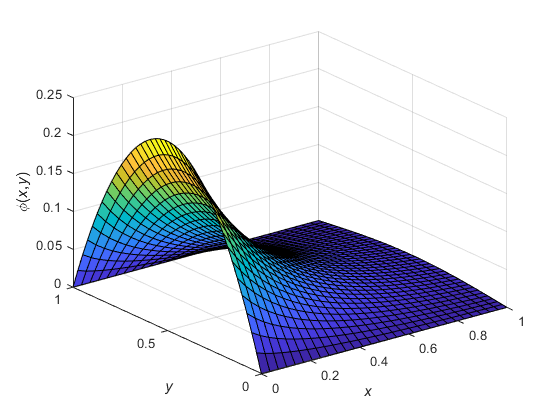

x = linspace(0,1,30);
y = linspace(0,1,40);
[X,Y]  = meshgrid(x, y);
Phi = zeros(40,30);
for k = 1:20
    Phi = Phi+4*(1-cos(k*pi))/(k*pi)^3*exp(-k*X*pi).*sin(k*Y*pi);
end
surf(x, y, Phi)
xlabel('\itx')
ylabel('\ity')
zlabel('\phi(\itx\rm,\ity\rm)')

# Rewrites the previous program using nested for-loops.

x = linspace(0,1,30);
y = linspace(0,1,40);
[X,Y]  = meshgrid(x, y);
Phi = zeros(40,30);
for i = 1:40
    for j = 1:30
        for k = 1:20
            Phi(i,j) = Phi(i,j)+4*(1-cos(k*pi))/(k*pi)^3 ...
                *exp(-k*X(i,j)*pi)*sin(k*Y(i,j)*pi);
        end
    end
end
surf(x, y, Phi)
xlabel('\itx')
ylabel('\ity')
zlabel('\phi(\itx\rm,\ity\rm)')

# Rewrites Example02_15b as a user-defined function which allows the input of m, k, c, delta, and t and outputs period T and displacement x.

Demonstrates the use of the user-defined function Example03_05a.

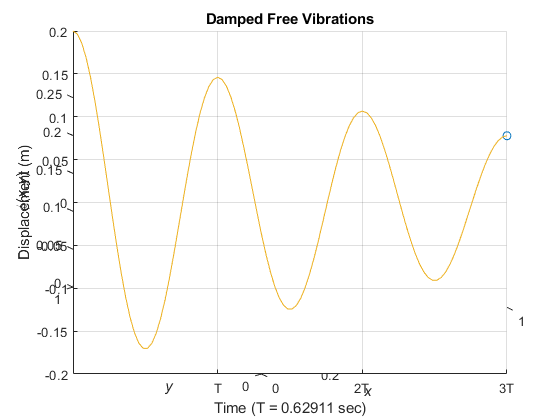

mass = 1; spring = 100; damper = 1; delta = 0.2;
time = 0;
T = CallFunction(mass, spring, damper, delta, time);
time = linspace(0, 3*T, 100);
[T, response] = CallFunction(mass, spring, damper, delta, time);
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2])
grid on
hold on
comet(time, response)
title('Damped Free Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')

# Demonstrates the use of the user-defined function Example03_05a.

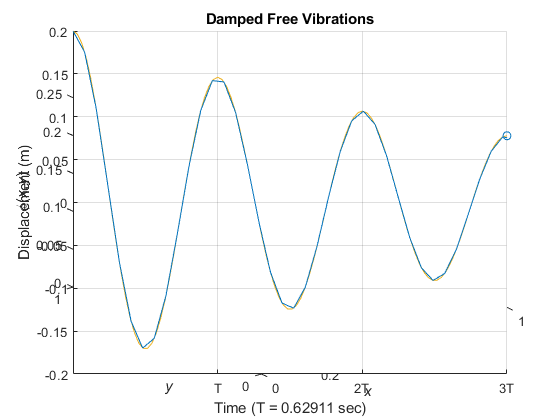

time = linspace(0,5,100);
[period,response] = CallFunction(1,100,1,0.2,time);
plot(time,response);

CallFunction(1,100,1,0.2,time);

# Combines Example03_05a and Example03_05c into a file.

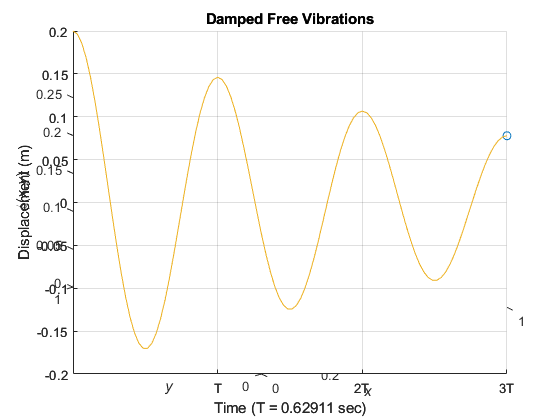

clear
mass = 1; spring = 100; damper = 1; delta = 0.2;
time = 0;
T = UDFV1(mass, spring, damper, delta, time);
time = linspace(0, 3*T, 100);
[T, response] = UDFV1(mass, spring, damper, delta, time);
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2])
grid on
hold on
comet(time, response)
title('Damped Free Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')

# Modifies Example03_06a, so it can be executed in all versions of MATLAB

MainFunction() function MainFunction

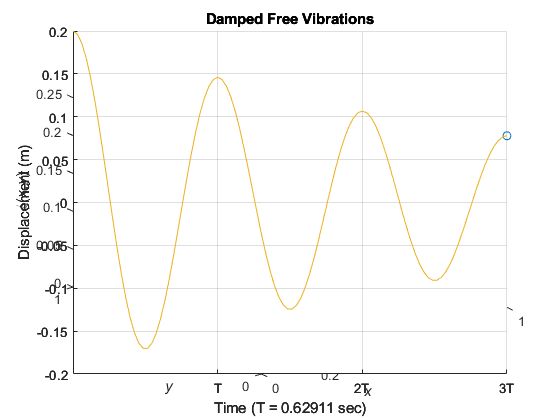

mass = 1; spring = 100; damper = 1; delta = 0.2;
time = 0;
T = UDFV2(mass, spring, damper, delta, time);
time = linspace(0, 3*T, 100);
[T, response] = UDFV2(mass, spring, damper, delta, time);
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2])
grid on
hold on
comet(time, response)
title('Damped Free Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')

% end

# Modifies Example01_18 to include nested functions, so the use of global variables becomes unnecessary.

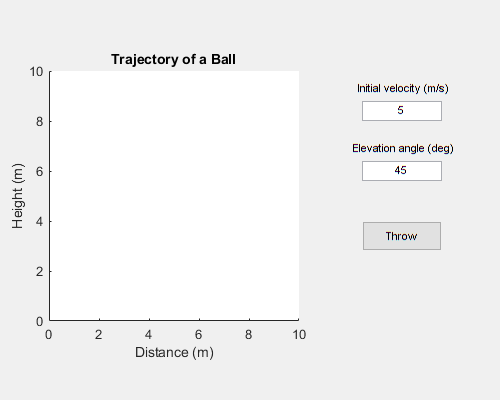

global g velocityBox angleBox
g = 9.81;
figure('position',[30,70,500,400])
axes('Units','pixels','Position',[50,80,250,250])
axis([0,10,0,10])
xlabel('Distance (m)'),ylabel('Height (m)')
title('Trajectory of a Ball')

uicontrol('Style', 'text', 'String', 'Initial velocity (m/s)', 'Position', [330,300,150,20])
velocityBox = uicontrol('Style', 'edit', 'String', '5', 'Position', [363,280,80,20]);
uicontrol('Style', 'text', 'String', 'Elevation angle (deg)','Position', [330,240,150,20])
angleBox = uicontrol('Style', 'edit', 'String', '45', 'Position', [363,220,80,20]);
uicontrol('Style', 'pushbutton', 'String', 'Throw','Position', [363,150,80,30],'Callback', @pushbuttonCallback)

# Demonstrates the use of function handles

handle = @oscillation1; %@自定義函數名稱
x1 = fzero(handle, 0.2) %fzero(funct,猜測值) 尋找函數根

Simplified version


x1 = 0.5000

x2 = fzero(handle, 0.5)

Simplified version


x2 = 0.5000

x3 = fzero(handle, 0.8)

Simplified version


x3 = 0.8333

# Implements a version of fzero, using a simple method.

handle = @oscillation2; 
x1 = fzero(handle, 0.1)

Simplified version


x1 = 0.1667

x2 = fzero(handle, 0.4)

Simplified version


x2 = 0.5000

x3 = fzero(handle, 0.8)

Simplified version


x3 = 0.8333


function x = fzero(handle, x0)
tolerance = 1.0e-6;
step = 0.01;
x = x0;
s1 = sign(handle(x));
while step/x > tolerance
    if s1 == sign(handle(x+step)) % sign符號函數
        x = x+step;
    else
        step = step/2;
    end
end
disp('Simplified version')
end

# Function

function [T, x] = UDFV1(m, k, c, delta, t)
omega = sqrt(k/m);
cC = 2*m*omega;
if c>= cC
    disp('Not an under-damped system!')
    T = 0; x = 0;
    return;
end
omegaD = omega*sqrt(1-(c/cC)^2);
T = 2*pi/omegaD;
x = delta*exp(-c*t/(2*m)).*(cos(omegaD*t)+c/(2*m*omegaD)*sin(omegaD*t));
end

function [T, x] = UDFV2(m, k, c, delta, t)
omega = sqrt(k/m);
cC = 2*m*omega;
if c>= cC
    disp('Not an under-damped system!')
    T = 0; x = 0;
    return;
end
omegaD = omega*sqrt(1-(c/cC)^2);
T = 2*pi/omegaD;
x = delta*exp(-c*t/(2*m)).*(cos(omegaD*t)+c/(2*m*omegaD)*sin(omegaD*t));
end

function pushbuttonCallback(angleBox,velocityBox,pushButton, ~)
    global g velocityBox angleBox
    v0 = str2double(velocityBox.String);
    theta = str2double(angleBox.String)*pi/180;
    t1 = 2*v0*sin(theta)/g;
    t = 0:0.01:t1;
    x = v0*cos(theta)*t;
    y = v0*sin(theta)*t-g*t.^2/2;
    hold on
    comet(x, y)
end

function fx = oscillation1(x)
fx = exp(-4*x)*cos(3*pi*x);
end

function fx = oscillation2(x)
fx = exp(-4*x)*cos(3*pi*x);
end